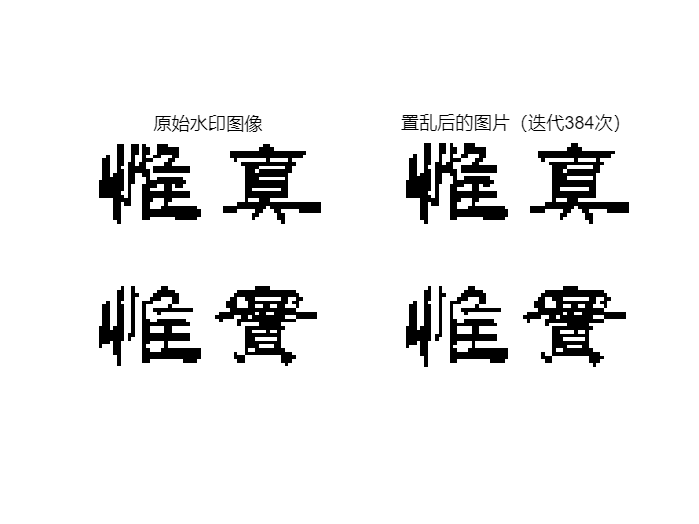

clear all;
close all;
clc;

img=imread('水印(二值).bmp');%读取图片，根据Arnold变换的条件，图像必须是正方形
mysize=size(img);%当只有一个输出参数时，返回一个行向量，该行向量的第一个元素时矩阵的行数，第二个元素是矩阵的列数。
if numel(mysize)>2%如果输入是彩色图像
   img=rgb2gray(img); %将彩色到灰度图像的转换
   fprintf("图像为彩色图\n");  %其中\r或者\n表示换行
end
subplot(1,2,1);
imshow(img,[])
title('原始水印图像');

% subplot(2,2,2);
% imhist(img)	%原图的直方图统计

%如果输入的不是正方形图像，则打印如下
[h,w]=size(img);
if h>w
    img = imresize(img, [w w]);
    fprintf("图像长宽不一样，图像可能失真\r");
end
if h<w
    img = imresize(img, [h h]);  
    fprintf("图像长宽不一样,图像可能失真");
end
[h,w]=size(img);

%置乱与逆置乱必须采用共同参数的时候,就相当于密码，才能解密，让图像复原
n=384;%迭代次数
a=1;b=1;
N=h;%N代表图像宽高，宽高要一样

%置乱操作
imgnnn=zeros(h,w);
for i=1:n
    for y=1:h
        for x=1:w           
            xx=mod((x-1)+b*(y-1),N)+1;   %mod取余操作，(a,b)就是a除以b的余数
            yy=mod(a*(x-1)+(a*b+1)*(y-1),N)+1;        
            imgnnn(yy,xx)=img(y,x);                
        end
    end
    img=imgnnn;
end
imgnnn = uint8(imgnnn);

subplot(1,2,2);
imshow(img,[])%置乱后的图片
title('置乱后的图片（迭代384次）');

imwrite (imgnnn,'置乱后的图片.bmp');  %生成图像保存功能

%逆置乱复原
img2=imread('置乱后的图片.bmp');%读取置乱图片
for i=1:n
    for y=1:h
        for x=1:w            
            xx=mod((a*b+1)*(x-1)-b*(y-1),N)+1;%matlab索引中不能是0，要从1开始
            yy=mod(-a*(x-1)+(y-1),N)+1  ;        
            imgnnn(yy,xx)=img2(y,x);                   
        end
    end
    img2=imgnnn;
end
imgnnn = uint8(imgnnn);
% subplot(2,2,4);
% imshow(imgnnn,[])
% title('逆置乱的复原图片');
% imwrite(imgnnn,'逆置乱的复原图片.bmp');%生成图像保存功能
